% This code was generated via ChatGPT 5.4 ("extended thinking").

%% F-16A Level 1 Sizing Analysis — Class-Based Example
% This live script performs a Level 1 sizing pass for the F-16A example using
% the toolkit classes supplied with the project.
%
% Main objects used:
%   * AircraftDesign
%   * GeometryLevel1
%   * AeroLevel1
%   * PropulsionLevel1
%   * WeightLevel1
%   * MissionAnalysisLevel1
%   * ConstraintAnalysisClass
%   * Requirements
%   * SizingClassLevel1
%
% The script assumes the corresponding class files, import utilities, design
% workbook, requirements table, constraints table, and mission profile are on
% the MATLAB path.

% clear; clc; close all;

%% Project setup
% Set this to the folder containing your classes, import utilities, design
% spreadsheet/workbook, requirements file, constraints file, and mission data.
projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";

% Basic class availability check. This catches path/name issues before the
% design object tries to import data.
requiredClasses = [ ...
    "AircraftDesign", ...
    "GeometryLevel1", ...
    "AeroLevel1", ...
    "PropulsionLevel1", ...
    "WeightLevel1", ...
    "MissionAnalysisLevel1", ...
    "ConstraintAnalysisClass", ...
    "Requirements", ...
    "SizingClassLevel1"];

for k = 1:numel(requiredClasses)
    assertClassOrFileExists(requiredClasses(k));
end

%% Create the aircraft design object
% AircraftDesign is the project-level object. It imports the design geometry,
% fuselage data, propulsion data, weight data, general aircraft data, and
% requirements reference.

design = AircraftDesign( ...
    designName, ...
    RequirementsName = requirementsName, ...
    ConstraintsName  = constraintsName, ...
    AutoLoad         = true);


% Keep the constraints filename explicit in case the design constructor was
% given a blank or nonstandard value.
if strlength(string(design.constraints_filename)) == 0
    design.constraints_filename = constraintsName;
end

disp("AircraftDesign object created:")

AircraftDesign object created:


disp(design)

  AircraftDesign with properties:

                     Name: "F-16A Block 50"
                     geom: [1×1 struct]
                  general: [1×1 struct]
               propulsion: [1×1 struct]
          propulsion_type: "low bpr turbofan"
                  weights: [1×1 struct]
                     type: "Jet fighter"
             requirements: [1×1 struct]
    requirements_filename: []
     constraints_filename: "Constraints"
            WeightResults: []
              AeroResults: []
        PropulsionResults: []
           internalvolume: []


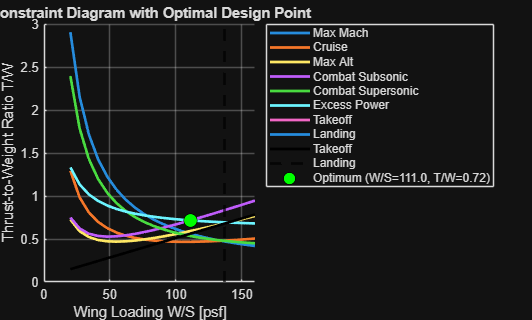

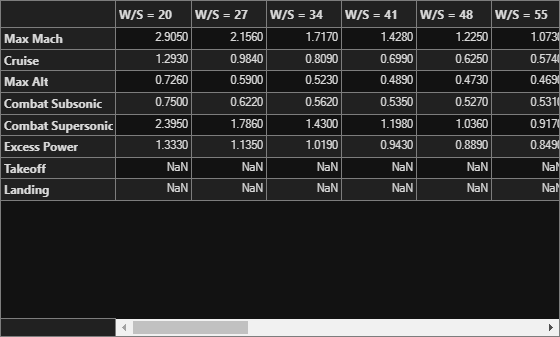


%% Build the Level 1 analysis objects
% These objects are intentionally lower-fidelity than the Level 3 versions.
% They rely on historical estimates, tabulated assumptions, and simple mission
% weight fractions/Breguet-style estimates.

geometry_obj     = GeometryLevel1(design);
aero_obj         = AeroLevel1();
propulsion_obj   = PropulsionLevel1(design);
weight_obj       = WeightLevel1(design);
mission_obj      = MissionAnalysisLevel1(missionName);
constraint_obj   = ConstraintAnalysisClass(design);

requirements_obj = Requirements(design);
sizing_obj       = SizingClassLevel1();

% ConstraintAnalysisClass may either populate its properties directly or, if
% it behaves as a value class in your local inheritance tree, return the values
% through constraint_analysis(). This helper supports both behaviors.
[constraint_obj, constraintResults] = ensureConstraintResults(constraint_obj);

disp("Constraint-analysis summary:")

Constraint-analysis summary:


disp(constraintResults)

    OptimalWingLoading_psf    MinimumThrustLoading    LandingWingLoadingLimit_psf
    ______________________    ____________________    ___________________________
             111                    0.71662                     136.86           



%% Check Level 1 inputs used by the sizing loop
% These are the key scalar inputs that drive the Level 1 sizing closure.

inputSummary = table( ...
    string(design.type), ...
    string(design.propulsion_type), ...
    weight_obj.W_TO_guess, ...
    weight_obj.W_fixed, ...
    constraint_obj.optimal_WS, ...
    constraint_obj.min_TW, ...
    propulsion_obj.TSFC.cruise * 3600, ...
    propulsion_obj.TSFC.loiter * 3600, ...
    'VariableNames', { ...
    'AircraftType', ...
    'PropulsionType', ...
    'InitialWTOGuess_lbf', ...
    'FixedWeight_lbf', ...
    'OptimalWingLoading_psf', ...
    'RequiredThrustLoading', ...
    'CruiseTSFC_per_hr', ...
    'LoiterTSFC_per_hr'});

disp(inputSummary)

    AircraftType       PropulsionType      InitialWTOGuess_lbf    FixedWeight_lbf    OptimalWingLoading_psf    RequiredThrustLoading    CruiseTSFC_per_hr    LoiterTSFC_per_hr
    _____________    __________________    ___________________    _______________    ______________________    _____________________    _________________    _________________
    "Jet fighter"    "low bpr turbofan"           45000                5100                   111                     0.71662                  0.8                  0.7       



missionSummary = summarizeMissionData(mission_obj.missiondata);
disp("Mission-profile summary extracted from mission_obj.missiondata:")

Mission-profile summary extracted from mission_obj.missiondata:


disp(missionSummary)

     Segment      MachNumber    Altitude_ft     Range_ft     Time_min    PayloadDrop_lbf
    __________    __________    ___________    __________    ________    _______________
    "Startup"           0              0              NaN      NaN               0      
    "Taxi"              0              0              NaN      NaN               0      
    "Takeoff"        0.87              0              NaN      NaN               0      
    "Climb"          0.87          40000              NaN      NaN               0      
    "Cruise"         0.87          40000       1.1545e+06      NaN               0      
    "Dash"            1.6          40000       3.0381e+05      NaN               0      
    "Combat"          0.8          25000              NaN        2            4400  


%% Run the project sizing class
% This calls your SizingClassLevel1 method directly. The method returns the
% converged W_TO. In the current class definition, results_table is assigned
% inside the method, but the class itself does not inherit handle, so the table
% may not persist outside the method depending on your inheritance tree.

W_TO_from_sizing_class = sizing_obj.size_aircraft( ...
    design, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj, ...
    propulsion_obj, ...
    constraint_obj, ...
    requirements_obj, ...
    aero_obj);

     WTO     W_fixed    Fuel_fraction    Empty_weight_fraction    Empty_weight    WTO_new    Difference    Percent_Diff
    _____    _______    _____________    _____________________    ____________    _______    __________    ____________
    45000     5100         0.17375              0.58116              26152         38628       -6371.5         -14.159 
    38628     5100         0.17435              0.59281              22899         34353       -4275.2         -11.068 
    34353     5100         0.17469              0.60192              20678         31439       -2913.9          -8.482 
    31439     5100         0.17485               0.6089              19143         29429       -2009.9         -6.3929 
    2942


fprintf("\nSizingClassLevel1 returned W_TO = %.3f lbf\n", W_TO_from_sizing_class);


SizingClassLevel1 returned W_TO = 24676.180 lbf



%% Reconstruct a persistent iteration trace using the same Level 1 objects
% This loop mirrors the logic in SizingClassLevel1, but returns the iteration
% table to the live script for plots and inspection.
%
% It does not create a separate F-16 object. The design data still comes from
% AircraftDesign and the calculations are still performed through the Level 1
% objects supplied above.

[results_table, finalState] = runLevel1SizingTrace( ...
    design, ...
    geometry_obj, ...
    mission_obj, ...
    weight_obj, ...
    propulsion_obj, ...
    constraint_obj, ...
    requirements_obj, ...
    aero_obj);

disp("Persistent Level 1 sizing iteration table:")

Persistent Level 1 sizing iteration table:


disp(results_table)

    Iteration    WTO_lbf    FixedWeight_lbf    FuelUsed_lbf    FuelFraction    EmptyWeightFraction    OEW_lbf    WingReferenceArea_ft2    WettedArea_ft2    WettedAspectRatio    LDmax     SeaLevelStaticThrust_lbf    WTO_new_lbf    Difference_lbf    PercentDifference
    _________    _______    _______________    ____________    ____________    ___________________    _______    _____________________    ______________    _________________    ______    ________________________    ___________    ______________


%% Final sizing summary

finalSummary = table( ...
    finalState.W_TO_lbf, ...
    finalState.W_empty_lbf, ...
    finalState.W_fixed_lbf, ...
    finalState.W_fuel_lbf, ...
    finalState.fuel_fraction, ...
    finalState.empty_weight_fraction, ...
    finalState.S_ref_ft2, ...
    finalState.S_wet_ft2, ...
    finalState.AR_wetted, ...
    finalState.LDmax, ...
    finalState.T0_lbf, ...
    'VariableNames', { ...
    'WTO_lbf', ...
    'OEW_lbf', ...
    'FixedWeight_lbf', ...
    'FuelUsed_lbf', ...
    'FuelFraction', ...
    'EmptyWeightFraction', ...
    'WingReferenceArea_ft2', ...
    'WettedArea_ft2', ...
    'WettedAspectRatio', ...
    'LDmax', ...
    'SeaLevelStaticThrust_lbf'});

disp("Final Level 1 sizing summary:")

Final Level 1 sizing summary:


disp(finalSummary)

    WTO_lbf    OEW_lbf    FixedWeight_lbf    FuelUsed_lbf    FuelFraction    EmptyWeightFraction    WingReferenceArea_ft2    WettedArea_ft2    WettedAspectRatio    LDmax     SeaLevelStaticThrust_lbf
    _______    _______    _______________    ____________    ____________    ___________________    _____________________    ______________    _________________    ______    ________________________
     24676      15506          5100             4070.3         0.17484             0.62838                 222.31                1472.1             0.45304         9.4231             17683          


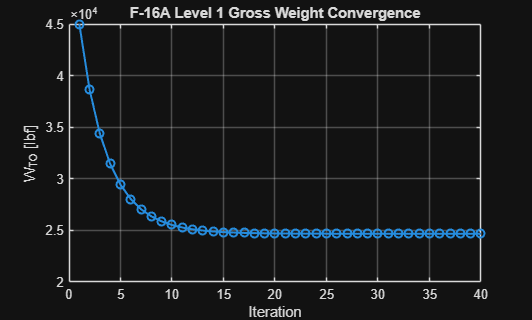


%% Plot gross-weight convergence

figure('Name', 'Level 1 Gross Weight Convergence');
plot(results_table.Iteration, results_table.WTO_lbf, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 1 Gross Weight Convergence');

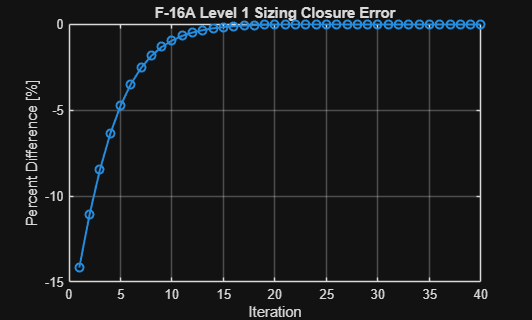


%% Plot closure error

figure('Name', 'Level 1 Closure Error');
plot(results_table.Iteration, results_table.PercentDifference, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 1 Sizing Closure Error');

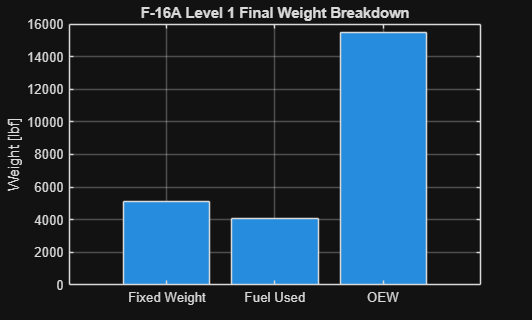


%% Plot final weight breakdown

weightBreakdown = table( ...
    categorical(["OEW"; "Fuel Used"; "Fixed Weight"]), ...
    [finalState.W_empty_lbf; finalState.W_fuel_lbf; finalState.W_fixed_lbf], ...
    'VariableNames', {'Component', 'Weight_lbf'});

figure('Name', 'Level 1 Final Weight Breakdown');
bar(weightBreakdown.Component, weightBreakdown.Weight_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 1 Final Weight Breakdown');


%% Save results into the AircraftDesign object
% AircraftDesign is a handle class, so these assignments persist on the design
% object during this MATLAB session.

design.WeightResults.Level1SizingTable = results_table;
design.WeightResults.Level1Summary     = finalSummary;
design.WeightResults.W_TO              = finalState.W_TO_lbf;
design.WeightResults.OEW               = finalState.W_empty_lbf;
design.WeightResults.FuelUsed          = finalState.W_fuel_lbf;

design.AeroResults.Level1.LDmax         = finalState.LDmax;
design.AeroResults.Level1.AR_wetted     = finalState.AR_wetted;
design.AeroResults.Level1.S_wet         = finalState.S_wet_ft2;

design.PropulsionResults.Level1.T0      = finalState.T0_lbf;
design.PropulsionResults.Level1.TSFC    = propulsion_obj.TSFC;

fprintf("\nSaved Level 1 sizing results into design.WeightResults, design.AeroResults, and design.PropulsionResults.\n");


Saved Level 1 sizing results into design.WeightResults, design.AeroResults, and design.PropulsionResults.



%% Local helper functions

function assertClassOrFileExists(className)
    className = string(className);
    existsAsClass = exist(char(className), 'class') == 8;
    existsAsFile  = exist(char(className + ".m"), 'file') == 2;

    if ~(existsAsClass || existsAsFile)
        error("Required class/file '%s' was not found on the MATLAB path. Check projectRoot/addpath.", className);
    end
end

function [constraint_obj, constraintResults] = ensureConstraintResults(constraint_obj)
    needsRun = isempty(constraint_obj.optimal_WS) || isempty(constraint_obj.min_TW);

    if needsRun
        [TW_table, T_Wto_takeoff, optimal_WS, min_TW, Landing, Wto_S_landing, T0_W0, W0_S_ref, T_Wto_required] = ...
            constraint_obj.constraint_analysis();

        constraint_obj.TW_table        = TW_table;
        constraint_obj.T_Wto_takeoff   = T_Wto_takeoff;
        constraint_obj.optimal_WS      = optimal_WS;
        constraint_obj.min_TW          = min_TW;
        constraint_obj.Landing         = Landing;
        constraint_obj.Wto_S_landing   = Wto_S_landing;
        constraint_obj.T0_W0           = T0_W0;
        constraint_obj.W0_S_ref        = W0_S_ref;
        constraint_obj.T_Wto_required  = T_Wto_required;
    end

    constraintResults = table( ...
        constraint_obj.optimal_WS, ...
        constraint_obj.min_TW, ...
        constraint_obj.Wto_S_landing, ...
        'VariableNames', {'OptimalWingLoading_psf', 'MinimumThrustLoading', 'LandingWingLoadingLimit_psf'});
end

function missionSummary = summarizeMissionData(missiondata)
    segmentNames = fieldnames(missiondata);
    rows = strings(0, 1);
    mach = nan(0, 1);
    altitude = nan(0, 1);
    range = nan(0, 1);
    time = nan(0, 1);
    payloadDrop = nan(0, 1);

    for i = 1:numel(segmentNames)
        name = segmentNames{i};
        segment = missiondata.(name);

        rows(end+1, 1) = string(name);
        mach(end+1, 1) = getFieldOrNaN(segment, 'MachNumber');
        altitude(end+1, 1) = getFieldOrNaN(segment, 'Altitudeft');
        range(end+1, 1) = getFieldOrNaN(segment, 'Rangeft');
        time(end+1, 1) = getFieldOrNaN(segment, 'Timemin');
        payloadDrop(end+1, 1) = getFieldOrNaN(segment, 'PayloadDroplbf');
    end

    missionSummary = table(rows, mach, altitude, range, time, payloadDrop, ...
        'VariableNames', {'Segment', 'MachNumber', 'Altitude_ft', 'Range_ft', 'Time_min', 'PayloadDrop_lbf'});
end

function value = getFieldOrNaN(s, fieldName)
    if isstruct(s) && isfield(s, fieldName)
        value = s.(fieldName);
    elseif istable(s) && any(strcmp(s.Properties.VariableNames, fieldName))
        value = s.(fieldName);
    else
        value = NaN;
    end

    if ~isscalar(value) || ~isnumeric(value)
        value = NaN;
    end
end

function [results_table, finalState] = runLevel1SizingTrace(design, geometry_obj, mission_obj, weight_obj, propulsion_obj, constraint_obj, requirements_obj, aero_obj)
    %#ok<INUSD> requirements_obj is kept here to preserve the same object signature as SizingClassLevel1.

    W_S = constraint_obj.optimal_WS;
    T_W = constraint_obj.min_TW;

    assert(~isempty(W_S) && isfinite(W_S), 'constraint_obj.optimal_WS must be finite.');
    assert(~isempty(T_W) && isfinite(T_W), 'constraint_obj.min_TW must be finite.');

    W_TO = weight_obj.W_TO_guess;
    W_fixed = mission_obj.missiondata.Startup.PayloadFixedlbf;

    tol = 1e-3;
    maxIteration = 40;
    rows = [];

    for iteration = 1:maxIteration
        geometry_obj.mainwings.S_ref = W_TO / W_S;
        geometry_obj.design.S_wet = geometry_obj.get_design_S_wet(W_TO);

        propulsion_obj.T0 = T_W * W_TO;

        weight_obj.W_TO = W_TO;
        weight_obj.W_fixed = W_fixed;

        [fuel_used, fuel_fraction] = mission_obj.get_mission_fuel( ...
            constraint_obj, ...
            design, ...
            geometry_obj, ...
            propulsion_obj, ...
            weight_obj, ...
            aero_obj);

        OEW = weight_obj.get_OEW(design.type, W_TO);
        OEW_frac = OEW / W_TO;

        W_TO_new = fuel_used + W_fixed + OEW;
        difference = W_TO_new - W_TO;
        percentDifference = 100 * difference / W_TO;

        AR_wetted = aero_obj.compute_AR_wetted( ...
            geometry_obj.mainwings.AR, ...
            geometry_obj.design.S_wet, ...
            geometry_obj.mainwings.S_ref);

        LDmax = aero_obj.get_LDmax(geometry_obj, design.general.Type);

        rows(end+1, :) = [ ...
            iteration, ...
            W_TO, ...
            W_fixed, ...
            fuel_used, ...
            fuel_fraction, ...
            OEW_frac, ...
            OEW, ...
            geometry_obj.mainwings.S_ref, ...
            geometry_obj.design.S_wet, ...
            AR_wetted, ...
            LDmax, ...
            propulsion_obj.T0, ...
            W_TO_new, ...
            difference, ...
            percentDifference]; %#ok<AGROW>

        if abs(difference) < tol
            W_TO = W_TO_new;
            break;
        end

        W_TO = W_TO_new;
    end

    results_table = array2table(rows, 'VariableNames', { ...
        'Iteration', ...
        'WTO_lbf', ...
        'FixedWeight_lbf', ...
        'FuelUsed_lbf', ...
        'FuelFraction', ...
        'EmptyWeightFraction', ...
        'OEW_lbf', ...
        'WingReferenceArea_ft2', ...
        'WettedArea_ft2', ...
        'WettedAspectRatio', ...
        'LDmax', ...
        'SeaLevelStaticThrust_lbf', ...
        'WTO_new_lbf', ...
        'Difference_lbf', ...
        'PercentDifference'});

    last = results_table(end, :);

    finalState = struct();
    finalState.W_TO_lbf = last.WTO_new_lbf;
    finalState.W_empty_lbf = last.OEW_lbf;
    finalState.W_fixed_lbf = last.FixedWeight_lbf;
    finalState.W_fuel_lbf = last.FuelUsed_lbf;
    finalState.fuel_fraction = last.FuelFraction;
    finalState.empty_weight_fraction = last.EmptyWeightFraction;
    finalState.S_ref_ft2 = last.WingReferenceArea_ft2;
    finalState.S_wet_ft2 = last.WettedArea_ft2;
    finalState.AR_wetted = last.WettedAspectRatio;
    finalState.LDmax = last.LDmax;
    finalState.T0_lbf = last.SeaLevelStaticThrust_lbf;
end
